clc
clear
% close all
s = tf('s');

Parsing data

load meass/ident01.mat

t = data(:,1);

posX_cart = data(:,3);
posY_cart = data(:,7);

posX_effector = data(:,4);
posY_effector = data(:,8);

input_voltage_x = data(:,5);
input_voltage_y = data(:,9);
% plot(t,posX_cart);
hold on

identification of cart

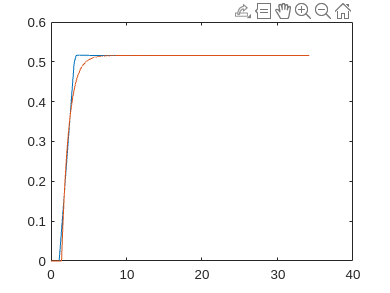

y = posX_cart;
ind1 = find_t(y,0.7); 
ind2 = find_t(y,0.33);

t1 = t(ind1);
t2 = t(ind2);

K = y(end);
T = 1.245*(t1-t2);
D = 1.498*t2-0.498*t1;

F = K/(1+T*s)*exp(-D*s);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
% plot(t_model,y_model)